In estimateModel.mlx, we learned that following structure is best:

first order no zeros plus delay.

In this file, we use tfest() to find a model of the system and then use procest() to find a model of the system plus a model of the noise filter. To test whether the noise filter is good, we perform residual analysis. Ideally, autocorrelation of residuals is low.

clear;
stepStruct = load("Simulated_stepdata.mat");
trainingStruct = load("Simulated_data1.mat");
validationStruct = load("Simulated_data2.mat");
Ts = trainingStruct.Ts;
dataStep = iddata(stepStruct.y, stepStruct.u, Ts, 'InterSample', 'zoh');
dataEst= iddata(trainingStruct.y, trainingStruct.u, Ts, 'Intersample', 'zoh');
dataVal = iddata(validationStruct.y, validationStruct.u, Ts, 'Intersample', 'zoh');
G_est = tfest(dataEst, 1, 0, NaN)

G_est =
 
  From input "u1" to output "y1":
                   0.5714
  exp(-0.28*s) * ----------
                 s + 0.8569
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using TFEST on time domain data "dataEst".
Fit to estimation data: 84.08%                      
FPE: 0.003304, MSE: 0.003291                        


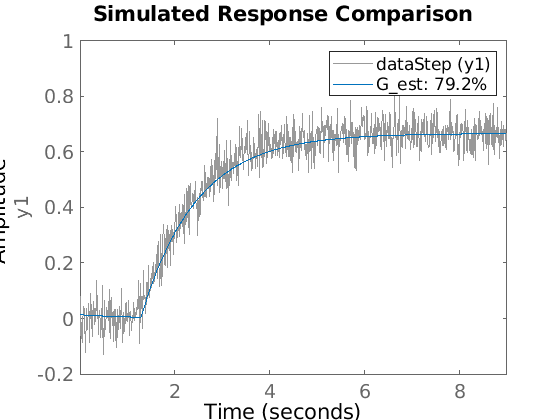

% form delay * (K / (1 + Ts))
compare(G_est, dataStep)

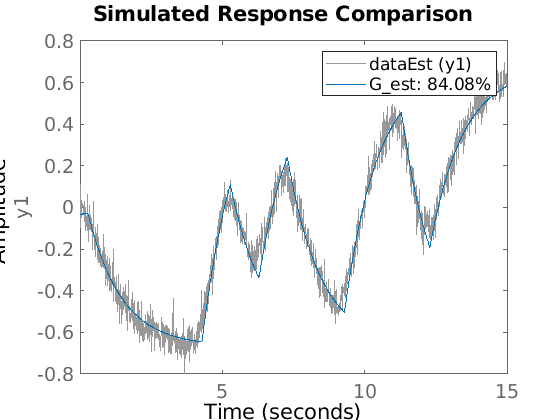

compare(G_est, dataEst)

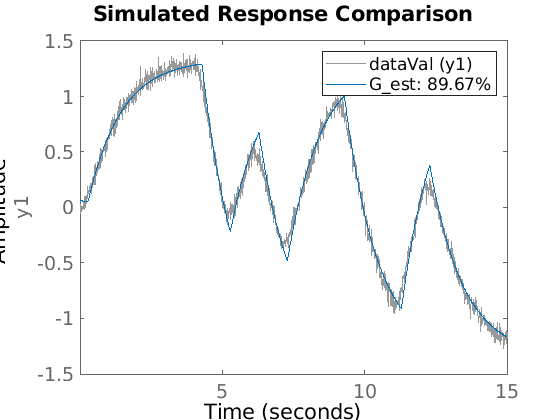

compare(G_est, dataVal)

K = G_est.Numerator / G_est.Denominator(2)

K = 0.6669

T = 1 / G_est.Denominator(2)

T = 1.1671

% provide initial values to optimization with procest() 
% initial values are obtained from the estimation of tfest()
sysInit = idproc('P1D','TimeUnit','seconds');
sysInit.Structure.Kp.Value    = K;
sysInit.Structure.Kp.Minimum  = 0;
sysInit.Structure.Tp1.Value   = T;
sysInit.Structure.Tp1.Maximum = 2 * T;
sysInit.Structure.Td.Value    = 0.28;
sysInit.Structure.Td.Minimum  = 0;
sysInit.Structure.Td.Maximum  = 2;
opt = procestOptions('DisturbanceModel','ARMA1');
sysP1D = procest(dataEst,sysInit,opt)

sysP1D =
Process model with transfer function:                
             Kp                                      
  G(s) = ---------- * exp(-Td*s)                     
          1+Tp1*s                                    
                                                     
        Kp = 0.68433                                 
       Tp1 = 1.2769                                  
        Td = 0.23585                                 
                                                     
An additive ARMA disturbance model has been estimated
      y = G u + (C/D)e                               
                                                     
      C(s) = s + 15.71                               
      D(s) = s + 3.66                                
                                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 5
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          

Evaluate the P1D model

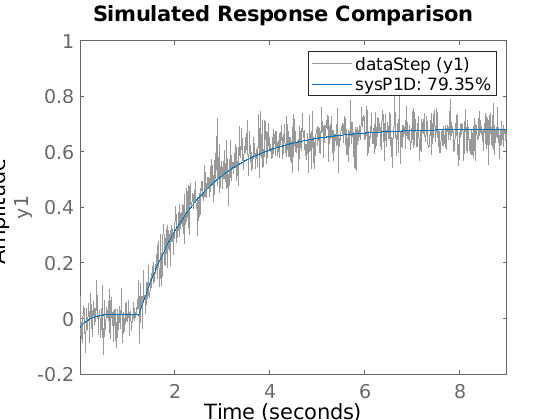

compare(sysP1D, dataStep)

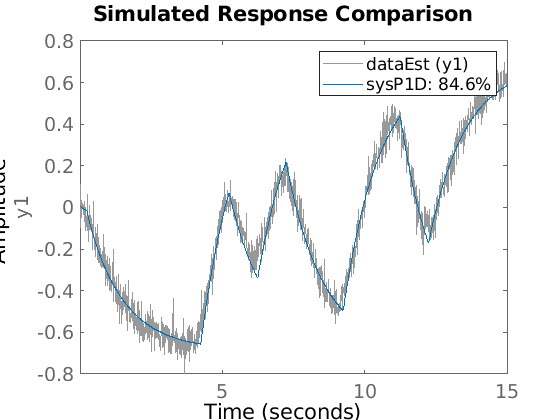

compare(sysP1D, dataEst)

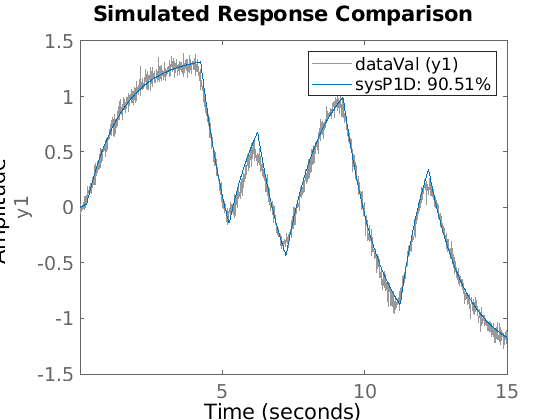

compare(sysP1D, dataVal)

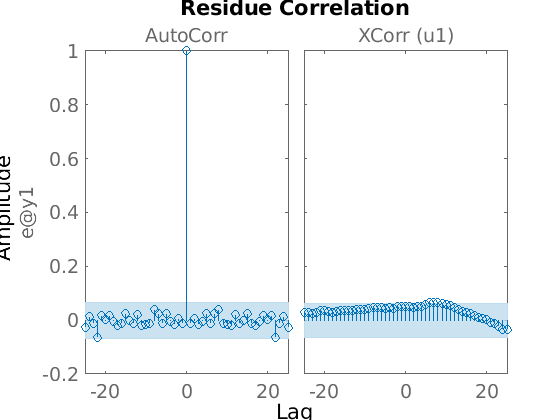

% residual analysis
resid(sysP1D, dataEst)

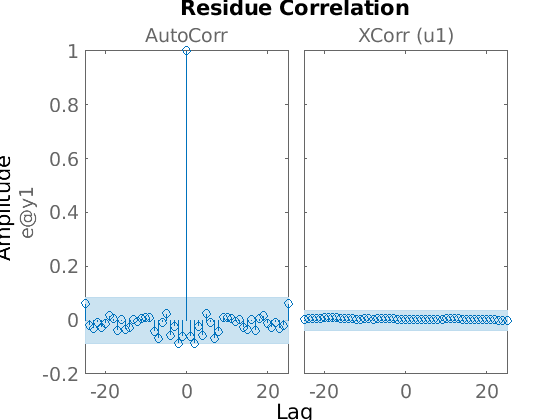

% resid(sysP1D, dataStep)

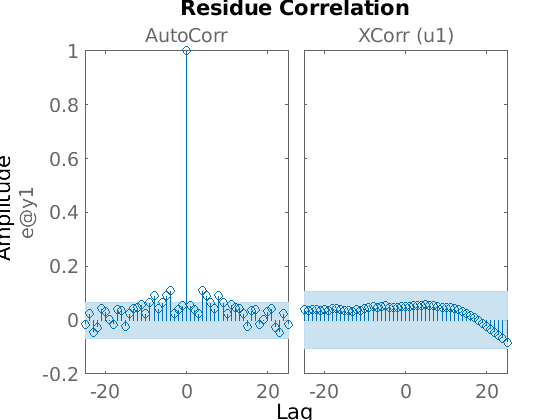

% resid(sysP1D, dataVal)

% some system properties
% steady state gain: rougly K from above
steadyStateGain = dcgain(sysP1D)

steadyStateGain = 0.6843

damp(sysP1D)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -7.83e-01     1.00e+00       7.83e-01         1.28e+00    


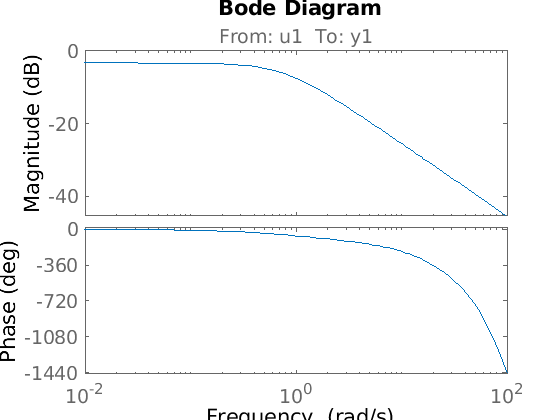

bode(sysP1D)

cutoffFrequency = 1 / sysP1D.Tp1

cutoffFrequency = 0.7831